addpath("C:\Users\roboime\Downloads\PROJETO GARRA DE LIXO - Copia\PROJETO GARRA DE LIXO - Copia\")
clear; clc;
pause(3);
rosIP = "192.168.187.128"; 
rosshutdown;

Shutting down global node /matlab_global_node_70605 with NodeURI http://192.168.187.1:61898/ and MasterURI http://192.168.187.128:11311.


pause(2);
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_81713 with NodeURI http://192.168.187.1:61927/ and MasterURI http://192.168.187.128:11311.


%cinemática Inversa

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: []
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'



jointSub = rossubscriber("/joint_states",'DataFormat','struct')
UR5e = loadrobot('universalUR5e');
initialIKGuess = homeConfiguration(UR5e);
initialIKGuess(1).JointPosition = 0.1;
initialIKGuess(4).JointPosition = -0.1;

% Adjust body transformations from previous URDF version
tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver

ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation

jointStateMsg = receive(jointSub,100) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]



initialIKGuess(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
initialIKGuess(2).JointPosition = jointStateMsg.Position(3);
initialIKGuess(3).JointPosition = jointStateMsg.Position(1);
initialIKGuess(4).JointPosition = jointStateMsg.Position(5);
initialIKGuess(5).JointPosition = jointStateMsg.Position(6);
initialIKGuess(6).JointPosition = jointStateMsg.Position(7);
pos1 = [-0.362763 -0.10707 0.252]; % x aqui é -y no gazebo ; y aqui é x no gazebo ; z mantém
pos2 = [ 0.667331 -0.077456 0.3 ];
pos3 = [ 0.460249 -0.170230 .3 ];
pos4 = [ -.618982 .220016 .248702];
pos6 = [-0.463792 0.346733 0.14]

pos6 =    -0.4638    0.3467    0.1400


gripperRotation = [-pi/2 -pi 0]; %  [Z Y X]radians

tform = eul2tform(gripperRotation); %
tform(1:3,4) = pos1'; % set translation in homogeneous transform

[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess)

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1598e-09
             ExitFlag: 1
               Status: 'success'



disp(configSoln)

  1×6 struct array with fields:

    JointName
    JointPosition



UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition]

UR5econfig =     2.3490   -0.1476    1.4976   -2.2015    0.0000   -0.0732


%iniciando nós ROS

%cliente Traj
[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct');
trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = [];

%Cliente Garra
[gripAct, gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory', 'control_msgs/FollowJointTrajectory', 'DataFormat', 'struct');
gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];
waitForServer(gripAct);

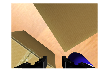

%camera RGB
rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);
imshow(rgbImg);


%detecção RGB

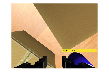

addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Color_Detector.mat','colorDetector'); 
imTest = rgbImg; 
[dbox,dscore,dlabel] = detect(colorDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

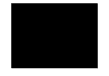

 pause(2);

%camera Depth
depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
depthMsg = receive(depthSub,3);
depthImg = rosReadImage(depthMsg);
imshow(depthImg);


%detecção Depth
addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);

pause(7);


%posição_incial

jointSub = rossubscriber("/joint_states",'DataFormat','struct')

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: []
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'


home = homeConfiguration(UR5e).JointPosition;

 % objeto 1
 jointStateMsg = receive(jointSub,100); % recebe a configuração atual do robô
 config_l = [UR5econfig(1) 0 0 0 0 0]; % ângulos iniciais dos elementos do robô
 k3 = 0.8;
 k4 = 1.02; % diminuir -> mais fechado.
 abrir_garra(0, gripGoal, gripAct);
 abrir_garra(0.5, gripGoal, gripAct);
 pause(3);
 config = rotelem(UR5econfig, [0.5 0.14 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 7);
 ajuste(config, 4, 0.28, 2, jointSub, trajGoal, trajAct, 5);
 pause(4);
 ajuste(config, 3, 0.7, 3, jointSub, trajGoal, trajAct, .8);
 pause(5);
 disp(config_l);
 abrir_garra(0, gripGoal, gripAct)
 pause(1);
 config_l = [0 0 0 0 -.1 0]; 
 jointStateMsg = receive(jointSub,100); % receive current robot configuration
 trajGoal = packTrajGoal(config_l,trajGoal, 3);
 sendGoal(trajAct,trajGoal);
 rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)

rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);

imshow(rgbImg);
addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Color_Detector.mat','colorDetector'); 
imTest = rgbImg; 
[dbox,dscore,dlabel] = detect(colorDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);
 pause(2); 


 depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
depthMsg = receive(depthSub,3);
depthImg = rosReadImage(depthMsg);
imshow(depthImg);


addpath('C:\Users\roboime\Downloads\');
load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
[dbox,dscore,dlabel] = detect(shapeDetector,imTest);
labelsWithScores = string(dlabel) + ": " + string(dscore);
imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
imshow(imTested);
 pause(2); 

% objeto 2
abrir_garra(0, gripGoal, gripAct);
initialIKGuess(2).JointPosition = 0.05;
tform = eul2tform(gripperRotation); %
tform(1:3,4) = pos2'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
disp(configSoln)
UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
pause(3);
config2 = rotelem(UR5econfig, [1 1 1 1 1.091 1], [5 2 3 4 1 6], jointSub, trajGoal, trajAct, 5);
pause(10);

config2 = ajuste(config2, 4, -.04, 5, jointSub, trajGoal, trajAct, 5);% -,035 o anterior
pause(1);
config2 = ajuste(config2, 2, -0.06, 5, jointSub, trajGoal, trajAct, 7);
pause(6);
abrir_garra(0.237,gripGoal,gripAct);
pause(10);
config2 = ajuste(config2, 2, 0.6, 2, jointSub, trajGoal, trajAct, 5);
config2 = ajuste(config2, 3, -2.3, 3, jointSub, trajGoal, trajAct, 5);
pause(10);
abrir_garra(0, gripGoal, gripAct);
pause(3);
config_l = [0 0 0 0 0 0]; 
jointStateMsg = receive(jointSub,100); % receive current robot configuration
trajGoal = packTrajGoal(config_l,trajGoal, 5);
sendGoal(trajAct,trajGoal);
pause(2);


% objeto 3
abrir_garra(0.1, gripGoal, gripAct);
initialIKGuess(2).JointPosition = 0.5;
initialIKGuess(3).JointPosition = -0.5;
tform = eul2tform(gripperRotation); %
tform(1:3,4) = pos3'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
disp(configSoln)
UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];

config = rotelem(UR5econfig, [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 3);
pause(5);
config = ajuste(config, 3, .4, 5, jointSub, trajGoal, trajAct, 3);
pause(2);
config = ajuste(config, 2, -.3, 5, jointSub, trajGoal, trajAct, 3);
config = ajuste(config, 4, -.13, 5, jointSub, trajGoal, trajAct, 3);
config = ajuste(config, 1, -.1, 5, jointSub, trajGoal, trajAct, 3);
config = ajuste(config, 3, -1.2, 5, jointSub, trajGoal, trajAct, 1);
pause(3);
home = [0 0 0 0 0 0];
trajGoal = packTrajGoal(home, trajGoal, 7);
sendGoal(trajAct, trajGoal);
abrir_garra(0.1, gripGoal, gripAct);
initialIKGuess(2).JointPosition = 0.2;
initialIKGuess(3).JointPosition = 0.5;
tform = eul2tform(gripperRotation);
tform(1:3,4) = pos4'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
disp(configSoln)
UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
config = rotelem(UR5econfig, [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 6, 1.5, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 2, 0.23, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 4, -.15, 3, jointSub, trajGoal, trajAct, 5);
pause(3);
config = ajuste(config, 3, -.03, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 2, 0.01, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 4, -.05, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 3, -.03, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 2, 0.02, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 4, -.02, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 3, -.01, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 2, 0.023, 3, jointSub, trajGoal, trajAct, 5);
abrir_garra(0.211, gripGoal, gripAct);
pause(5);
config = ajuste(config, 2, -.5, 3, jointSub, trajGoal, trajAct,10);
config = ajuste(config, 3 , -3.14, 5 , jointSub, trajGoal, trajAct, 10);
pause(5);
abrir_garra(0, gripGoal, gripAct);
config = ajuste(config, 2, 1.5, 3, jointSub, trajGoal, trajAct,10);
pause(6);
config = ajuste(config, 2, -2, 3, jointSub, trajGoal, trajAct, 5);
pause(3);

% objeto 5
abrir_garra(0, gripGoal, gripAct);
initialIKGuess(2).JointPosition = 0.2;
initialIKGuess(3).JointPosition = 0.5;
initialIKGuess(6).JointPosition = 1.5
tform = eul2tform(gripperRotation); %
tform(1:3,4) = pos4'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
disp(configSoln)
UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
config = rotelem(UR5econfig, [1 1 1 1.2 1 1], [4 1 3 2 5 6], jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 3, -.15, 2, jointSub, trajGoal, trajAct, 2);
pause(5);

config = ajuste(config, 1, .1, 5, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 4, .08, 5, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 5, -.05, 5, jointSub, trajGoal, trajAct, 5);
pause(6);
abrir_garra(.222, gripGoal, gripAct);%.235 a anterior
pause(10);
config = ajuste(config, 2, -.5, 3, jointSub, trajGoal, trajAct, 5);
config = ajuste(config, 3, +1, 3, jointSub, trajGoal, trajAct, 5);
pause(5);
abrir_garra(0, gripGoal, gripAct);

%objeto 6
abrir_garra(0.1, gripGoal, gripAct);
initialIKGuess(2).JointPosition = -0.5;
initialIKGuess(3).JointPosition = +0.5;
tform = eul2tform(gripperRotation); %
tform(1:3,4) = pos6'; % set translation in homogeneous transform
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess);
disp(configSoln)
UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
config = rotelem(UR5econfig, [1 1 1 1 1 1], [4 2 3 1 5 6], jointSub, trajGoal, trajAct, 15);
config = ajuste(config, 6, -.8, 4, jointSub, trajGoal, trajAct, 6);
pause(5);
config = ajuste(config, 2, .03, 4, jointSub, trajGoal, trajAct, 6);
pause(3);
abrir_garra(.3, gripGoal, gripAct);%.235 a anterior
pause(8);
config = ajuste(config, 2, -.7, 4, jointSub, trajGoal, trajAct, 6);
pause(3);
config = ajuste(config, 3, 1 , 4, jointSub, trajGoal, trajAct, 6);
pause(7);
abrir_garra(0, gripGoal, gripAct);